## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close

%% Load data
load area_rating_curve.txt
load kc.txt % [-]
load P.txt % [mm/h]
load Q_obs.txt %[m^3/s]
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7*3600;   %[m^3/h] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000*10^6;  %[m^2] Catchment area
phi = 38;       %[°] Latitude 

%% Reservoir parameters
Cq_sluice = 0.6; %discharge coefficient sluice gate [-]
Cq_spill = 0.7;  %discharge coefficient spillway [-]
L = 140;         %spillway length [m]
p = 19;          %level of spillway with respect to the empty pool level [m]

%% Power plant parameters
Q_T =35*3600;           %m^3/h turbine discharge
D = 3.3;                %pipe diameter [m]
L_p = 1200;             %pipe length [m]
ks = 0.0005;            %pipe roughness [m]
eta = 0.73;             %turbines efficiency [-]
delta_z = 75;           %difference of elevation between the empty pool level and the level of the tailrace [m]
lmin_HU = 7;            %minimum level for hydropower production with respect to the empty pool level [m]
v_T= Q_T/(pi*D^2/4);    %m/h velocity in turbine pipe

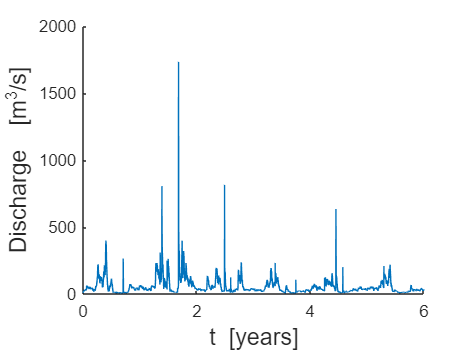

%% Plot discharge time series
figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

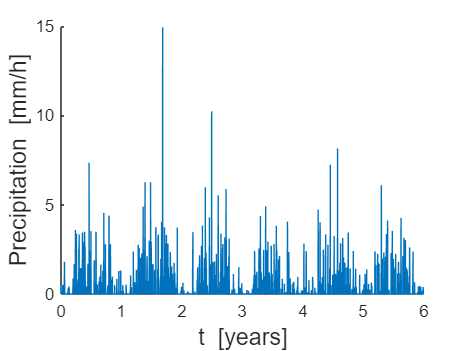


%% Plot precipitation time series
figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [mm/h]','FONTSIZE',14)      %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I = sum((temperature./5).^(1.514));
a = 6.75e-7*I^3-7.71e-5*I^2+1.79e-2*I+0.49; %experimental exponent
D = 1:365;
delt = 0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delt));
N_D = 24*w_s/pi;                            %number of daylight hours of day D
N_M =zeros(12,1);                           % mean daylight hours per day of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = (16.*(N_M/12).*(10*temperature/I).^a);   % [mm/h/unit area]
mean_monthly_ET0=ET_0./day_month';              %potential evapotranspiration in mm/day ; monthly
mean_monthly_ET0_hour=ET_0./day_month'/24/1000; % mean potential evapotranspiration in m/hour ; monthly

### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 10^(-6)*3600;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [m/s]
c = 10;                  %[-] Exponent for power-law relation L(s)  1<c<20
z = 1;           %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;             %[T] Mean sub-superficial residence time 1<t_sub<400 [h]
delta = [K_sat, c, z, t_sub];

% K_sat = 23.1423
% c = 16.4239
% z = 628.5144
% t_sub = 329.4774

% K_sat=0.0034; %m/h  
% c=6.8311;
% t_sub= 64.5218; %h
% z=0.5811; %m
% delta = [K_sat, c, z, t_sub];

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

### 4. Test the mass balance of your system in order to ensure a correct implementation.

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.

[Q_mod,R,I] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A,1);

NS_old = NS_fun(Q_obs*3600,Q_mod)

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

% K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 
% c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
% z = 2000;              %[L] Root zone depth 1<z<2000 [mm]

testS = 1.0000

testQ = 1.0000

% t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
% 

NS_old = 0.6517

% delta = [K_sat, c, z, t_sub];

K_sat = 10^(-6)*3600;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [m/s]
c = 10;                  %[-] Exponent for power-law relation L(s)  1<c<20
z = 1;           %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;             %[T] Mean sub-superficial residence time 1<t_sub<400 [h]
delta = [K_sat, c, z, t_sub];

ranges = [0.99^(-5)*(3600),19,1999/1000,399];
upper_lim = [10^(-5)*(3600),20,2000/1000,400];
lower_lim = [10^(-7)*(3600),1,1/1000,1];
sigma = 5/100;
cr = 1/1200;

[Q_mod,R,I] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A,0);

NS_old = NS_fun(Q_obs*3600,Q_mod)

### 3. Select a new parameter set by drawing from a truncated normal distribution centered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;

Niter=1000;
niter = 1 ; 
while niter<Niter
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma*delta_old(i),lower_lim(i),upper_lim(i));
    end
    [Q_mod,R,I] = hydrological_model(P/1000, mean_monthly_ET0_hour, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A,0);
    NS_new = NS_fun(Q_obs*3600,Q_mod)

NS_old = 0.6517

    
    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;

    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,niter))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.87
        break
    end
    niter=niter+1;
end

NS_new = 0.6592

NS_new = 0.6674

NS_new = 0.6459

NS_new = 0.6669

NS_new = 0.6398

NS_new = 0.6621

NS_new = 0.6944

NS_new = 0.7029

NS_new = 0.6870

NS_new = 0.7339

NS_new = 0.7381

NS_new = 0.7519

NS_new = 0.7694

NS_new = 0.7710

NS_new = 0.7589

NS_new = 0.7629

NS_new = 0.7652

NS_new = 0.7341

NS_new = 0.7462

NS_new = 0.7537

NS_new = 0.7353

NS_new = 0.7533

NS_new = 0.7474

NS_new = 0.7454

NS_new = 0.7605

NS_new = 0.7649

NS_new = 0.7545

NS_new = 0.7711

NS_new = 0.7620

NS_new = 0.7747

NS_new = 0.7816

NS_new = 0.7846

NS_new = 0.7699

NS_new = 0.7815

NS_new = 0.7797

NS_new = 0.7767

NS_new = 0.7810

NS_new = 0.7624

NS_new = 0.7792

NS_new = 0.7805

NS_new = 0.7725

NS_new = 0.7862

NS_new = 0.7968

NS_new = 0.7822

NS_new = 0.7885

NS_new = 0.7861

NS_new = 0.8095

NS_new = 0.8041

NS_new = 0.8192

NS_new = 0.8268

NS_new = 0.8355

NS_new = 0.8380

NS_new = 0.8342

NS_new = 0.8170

NS_new = 0.8257

NS_new = 0.8280

NS_new = 0.8271

NS_new = 0.8287

NS_new = 0.8336

NS_new = 0.8351

NS_new = 0.8272

NS_new = 0.8354

NS_new = 0.8327

NS_new = 0.8336

NS_new = 0.8264

NS_new = 0.8254

NS_new = 0.8345

NS_new = 0.8268

NS_new = 0.8311

NS_new = 0.8121

NS_new = 0.8449

NS_new = 0.8557

NS_new = 0.8523

NS_new = 0.8497

NS_new = 0.8578

NS_new = 0.8546

NS_new = 0.8372

NS_new = 0.8628

NS_new = 0.8567

NS_new = 0.8648

NS_new = 0.8635

NS_new = 0.8606

NS_new = 0.8564

NS_new = 0.8672

NS_new = 0.8660

NS_new = 0.8692

NS_new = 0.8699

NS_new = 0.8701

## Simulated discharge sequence

Run the calibrated hydrological model forced by the generated rainfall and obtain the discharge time series that will constitute the input of the reservoir.

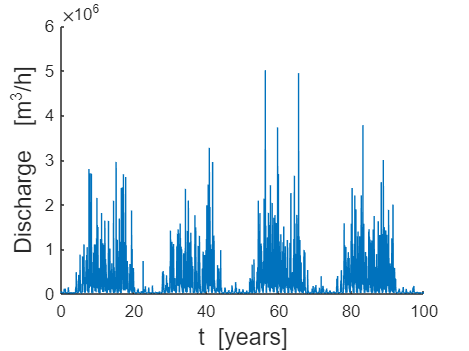

file = matfile("P_hourly.mat");
P_HOURLY = file.P_HOURLY;

[Q_simulated,R,I] = hydrological_model(P_HOURLY/1000, mean_monthly_ET0_hour, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A,0);

figure                                             
plot((1:length(Q_simulated))/(365*24),Q_simulated);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Discharge  [m^{3}/h]','FONTSIZE',14)       
box off 

## Reservoir routing and flood control

### 1. Compute the minimum flow target Q347

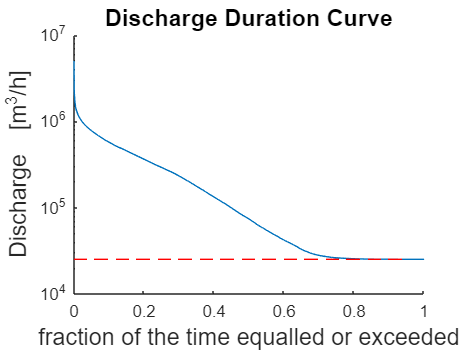

sort_Q=sort(Q_simulated,'descend');
p_exceedence=(1:length(Q_simulated))/length(Q_simulated);
figure
semilogy(p_exceedence,sort_Q)
title('Discharge Duration Curve','FONTSIZE',14)
xlabel('fraction of the time equalled or exceeded','FONTSIZE',14)                   
ylabel('Discharge  [m^{3}/h]','FONTSIZE',14) 
box off

Q347=sort_Q(find(p_exceedence>0.95,1,'first'));
hold on
plot([0 0.95],[Q347 Q347],'--r')

disp('The discharge that is exceeded 95% of the time is equal to'); Q_347=strcat(num2str(sort_Q(round(length(Q_simulated)*0.95))), ' m3/h')

The discharge that is exceeded 95% of the time is equal to


Q_347 = '25243.5996 m3/h'

### 2. Starting from the area rating curve, compute the volume rating curve (use trapezoidal approximation).

Determine the area rating curve

%area rating curve

level=area_rating_curve(:,1);          %"level": levels within the reservoir [m] above see level
level=level-level(1);                  %"level": levels with respect to the empty pool level (level(1))
lake_area=area_rating_curve(:,2);      %"lake_area": lake area corresponding to the "level" values


Determine the volume rating curve through the trapezoidal integration

%determination of the Volume rating curve (volume corresponding to the "level" values)
Volume=cumtrapz(level,lake_area);         %"Volume":volume corresponding to the "level" values


Plot them

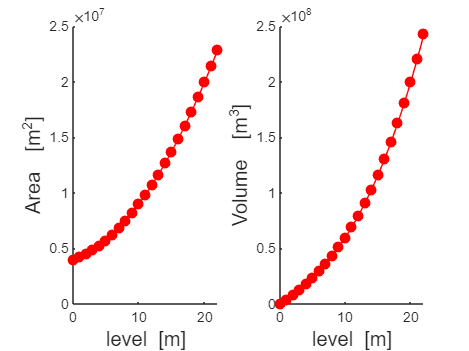

%plot area and volume rating curve
figure
subplot(1,2,1)
plot(level,lake_area,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)        %insert label x axis
ylabel('Area  [m^{2}]','fontsize',12)     %insert label y axis
box off
subplot(1,2,2)
plot(level,Volume,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)
ylabel('Volume  [m^{3}]','fontsize',12)
box off

### 3. Assume a value for the maximum level for hydroelectric use (e.g. 15 m) and compute the corresponding volume.

level_max = 15 %[m]

level_max = 15

volume_max = Volume(level_max+1) %[m^3]

volume_max = 116325000

### 4. For each time step of integration (∆t = 1 hour)

dt=1;                  %timestep of integration [h];

%variables preallocation
V=zeros(length(Q_simulated),1);           % volume time series
l=zeros(length(Q_simulated),1);           % level time series
sluice_A=zeros(length(Q_simulated),1);    % sluice gate opening time series
Qout=zeros(length(Q_simulated),1);        % outflowing dicharge time series
Q_HU=zeros(length(Q_simulated),1);        % discharge for hydropower time series
Q_WTP=zeros(length(Q_simulated),1);       % discharge to water treatment plant
Qg=zeros(length(Q_simulated),1);          % Sluice discharge

E=zeros(9,1);
p_flood=zeros(9,1);

%initial condition
V(1)=level_volume(Volume,level,p);   %initial volume (level equal to the spillway level)
l(1)=p; %[m]

